clear all; close all; clc; rng(1);

## Function to be learned

DEFECT: M = nr of layers, not nr of outputs. It works cose nr of layers = nr of outputs for this network. To be corrected to S_M

g = @(p) [ ...
             sin(pi * p(1)) + 0.5 * p(2);
             cos(pi * p(2)) + 0.5 * p(1)
         ];

p = [linspace(-2, 2, 50); linspace(-2, 2, 50)];

## Neural Network Architecture

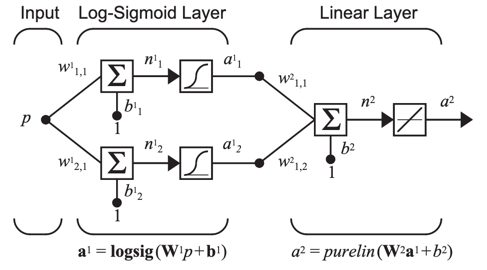

f  = {
        @(n) logsig(n)
        @(n) purelin(n)
     };
df = {
        @(n) logsig(n) .* (1 - logsig(n))
        @(n) ones(size(n))
     };

trainingData = twodi_TrainingData_Class();

for i = 1 : 1 : size(p, 2)
    trainingData.addTrainingSample("input", p(:, i), "output", g(p(:, i)));
end

**Visualize the data**

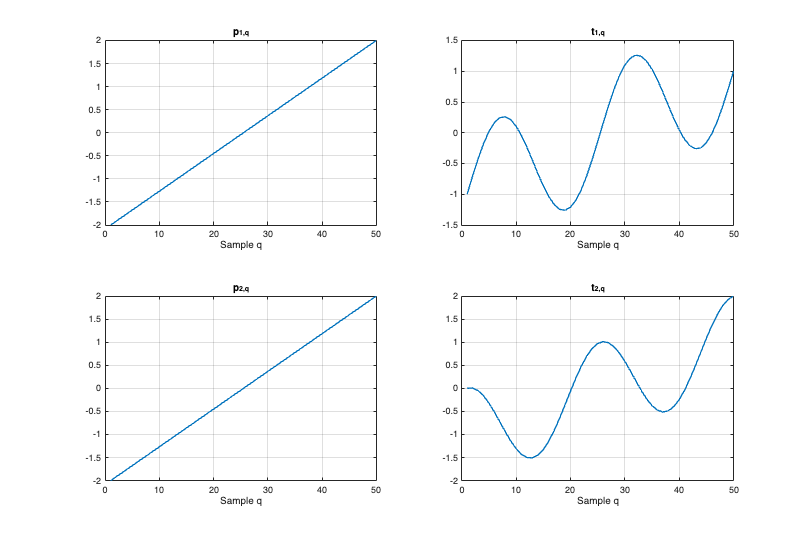

t = zeros(2, size(p, 2));
for q = 1:size(p, 2)
    t(:, q) = g(p(:, q));
end

figure('Position', [100 100 900 600]);
subplot(2, 2, 1); plot(1:size(p, 2), p(1, :), 'LineWidth', 1.5); grid on; xlabel('Sample q'); title('p_{1,q}');
subplot(2, 2, 2); plot(1:size(p, 2), t(1, :), 'LineWidth', 1.5); grid on; xlabel('Sample q'); title('t_{1,q}');
subplot(2, 2, 3); plot(1:size(p, 2), p(2, :), 'LineWidth', 1.5); grid on; xlabel('Sample q'); title('p_{2,q}');
subplot(2, 2, 4); plot(1:size(p, 2), t(2, :), 'LineWidth', 1.5); grid on; xlabel('Sample q'); title('t_{2,q}');

Q = trainingData.getNrOfTrainingSamples();

NR_OF_EPOCHS = 100;
mu = 0.01;

h = waitbar(0, 'Training progress...');
ITER = struct([]);
for epoch = 1 : 1 : NR_OF_EPOCHS

    ITER(epoch).network = twodi_NetworkMLP_Class(                                          ...
                                                 "nrOfLayers" , 2                        , ...
                                                 "nrOfInputs" , size(p, 1)               , ...
                                                 "nrOfNeurons", [20, size(g(p(:, 1)), 1)], ...
                                                 "actvnFcn"   , f                        , ...
                                                 "dActvnFcn"  , df                         ...
                                                 );
    if(epoch >= 2)
        ITER(epoch).network.setWeigths(ITER(epoch - 1).network.getWeights);
        ITER(epoch).network.setBiases(ITER(epoch - 1).network.getBiases);
    end

    M = ITER(epoch).network.getNrOfLayers;

            **Compute the Jacobian **$J=\frac{\partial \mathbb{v}}{\partial \mathbb{x}}|_{\mathbb{x}={\mathbb{x}}_k }$

    J = NaN(M * Q, ITER(epoch).network.getNrOfPrms);
    for q = 1 : 1 : Q

        [p_q, ~] = trainingData.getTrainingSample(q);

        J(((q - 1) * M + 1) : (q * M), :) = ITER(epoch).network.getBackprop__de_dx(p_q);
    
    end
    if any(isnan(J), 'all'), error('NaN detected in Jacobian J.'); end

           ** Compute the network error**

    v = NaN(M * Q, 1);
    for q = 1 : 1 : Q

        [p_q, t_q] = trainingData.getTrainingSample(q);
        [~  , a  ] = ITER(epoch).network.evaluate(p_q);

        v(((q - 1) * M + 1) : (q * M), 1) = t_q - a{M};

    end

**            Levenberg-Marquardt update. Recompute the sum of squared errors using **$\mathbb{x}+\Delta \mathbb{x}$

   network_test = twodi_NetworkMLP_Class(                                           ...
                                          "nrOfLayers" , 2                        , ...
                                          "nrOfInputs" , size(p, 1)               , ...
                                          "nrOfNeurons", [20, size(g(p(:, 1)), 1)], ...
                                          "actvnFcn"   , f                        , ...
                                          "dActvnFcn"  , df                         ...
                                         );
    while(1)

        x_new = ITER(epoch).network.getPrms() - (J' * J + mu * eye(size(J, 2))) \ (J' * v);
        network_test.setPrms(x_new);

        v_new = NaN(M * Q, 1);
        for q = 1 : 1 : Q
    
            [p_q, t_q] = trainingData.getTrainingSample(q);
            [~  , a  ] = network_test.evaluate(p_q);
    
            v_new(((q - 1) * M + 1) : (q * M), 1) = t_q - a{M};
        end

        if((v_new' * v_new) < (v' * v))
            mu = mu / 10;
            ITER(epoch).network.setPrms(x_new);
            break;
        else
            mu = mu * 10;
        end
    end

    clear network_test;

            **Compute the squared-error performance index**

    ITER(epoch).F = v' * v;
    ITER(epoch).index = epoch;

            **Update progress bar**

    waitbar(epoch / NR_OF_EPOCHS, h, sprintf('Training progress: %.1f%%', 100 * epoch / NR_OF_EPOCHS));
end
close(h);

## Validation

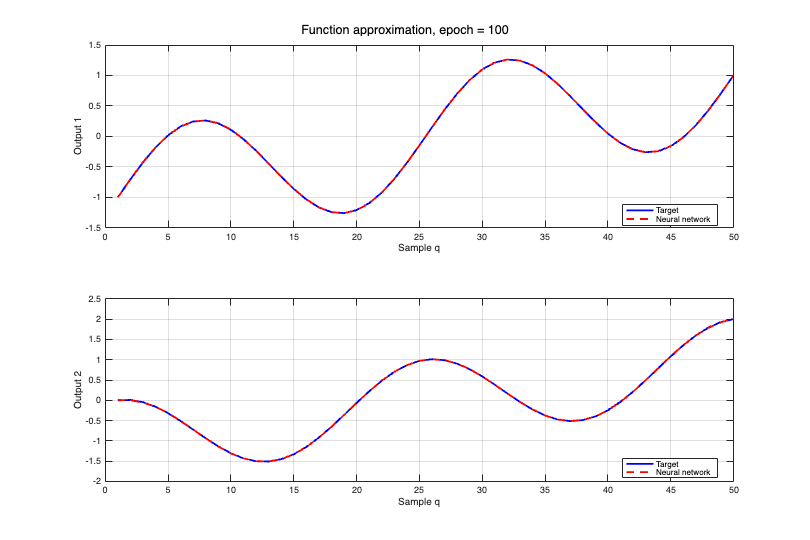

t_real = zeros(size(p));
for q = 1:size(p, 2)
    t_real(:, q) = g(p(:, q));
end

figure('Position', [100 100 900 600]);

h11 = subplot(2, 1, 1);
plot(1:size(p, 2), t_real(1, :), 'b-', 'LineWidth', 2); hold on;
h1 = plot(1:size(p, 2), nan(1, size(p, 2)), 'r--', 'LineWidth', 2);
grid on;
xlabel('Sample q');
ylabel('Output 1');
legend({'Target', 'Neural network'}, 'Location', 'best');

h22 = subplot(2, 1, 2);
plot(1:size(p, 2), t_real(2, :), 'b-', 'LineWidth', 2); hold on;
h2 = plot(1:size(p, 2), nan(1, size(p, 2)), 'r--', 'LineWidth', 2);
grid on;
xlabel('Sample q');
ylabel('Output 2');
legend({'Target', 'Neural network'}, 'Location', 'best');

for epoch = round(linspace(1, length(ITER), 100))

    network = ITER(epoch).network;
    y = zeros(size(t_real));

    for q = 1:size(p, 2)
        [~, a] = network.evaluate(p(:, q));
        y(:, q) = a{end};
    end

    set(h1, 'YData', y(1, :));
    set(h2, 'YData', y(2, :));

    sgtitle(sprintf('Function approximation, epoch = %d', epoch));

    drawnow;
    pause(0.1);
end

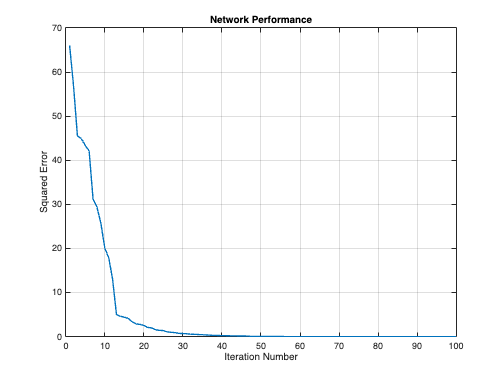

figure; plot([ITER.index], [ITER.F], 'LineWidth', 1.5); grid on; xlabel('Iteration Number'); ylabel('Squared Error'); title('Network Performance');